# MPC Distrubance Rejection

## Bluetooth

%% Connect to the HC-06 module
close all;
bt_connected = 0; % change it to 1 after connecting to bluetooth
if (bt_connected == 0)
    clear; 
    bt = Bluetooth("HC-06",1); % connects to the bluetooth module as a serial communication object
    fopen(bt); % initialize the serial object
end

flushoutput(bt);
fprintf(bt,num2str(0));

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;
inputGain = 2*kt/(R*r);

% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)];
C= [1 0 0 0];
D = 0;

% Discrete system
sys = ss(A,B,C,D);
sys_d = c2d(sys, 0.05, 'zoh');
fprintf("Rank of ctrb discrete system = %i", rank(ctrb(sys_d)));

Rank of ctrb discrete system = 4


A_d = sys_d.A;
B_d = sys_d.B;
C_d = sys_d.C;

## LQR

lqr_weight = [1e4 1 8e5 1];
Q_lqr = diag(lqr_weight);
R_lqr = 1;

% Discrete controller
K_d = dlqr(A_d, B_d, Q_lqr, R_lqr)

K_d =    -2.6759   -3.7758   33.8911    1.6567


% COntinuous controller
K = lqr(A,B,Q_lqr,R_lqr)

K =  -100.0000 -136.3993  920.2781   16.1640


%K = [0 0 6150 100];

## Closed Loop System

% Discrete closed loop
disp("Discrete LQR step")

Discrete LQR step


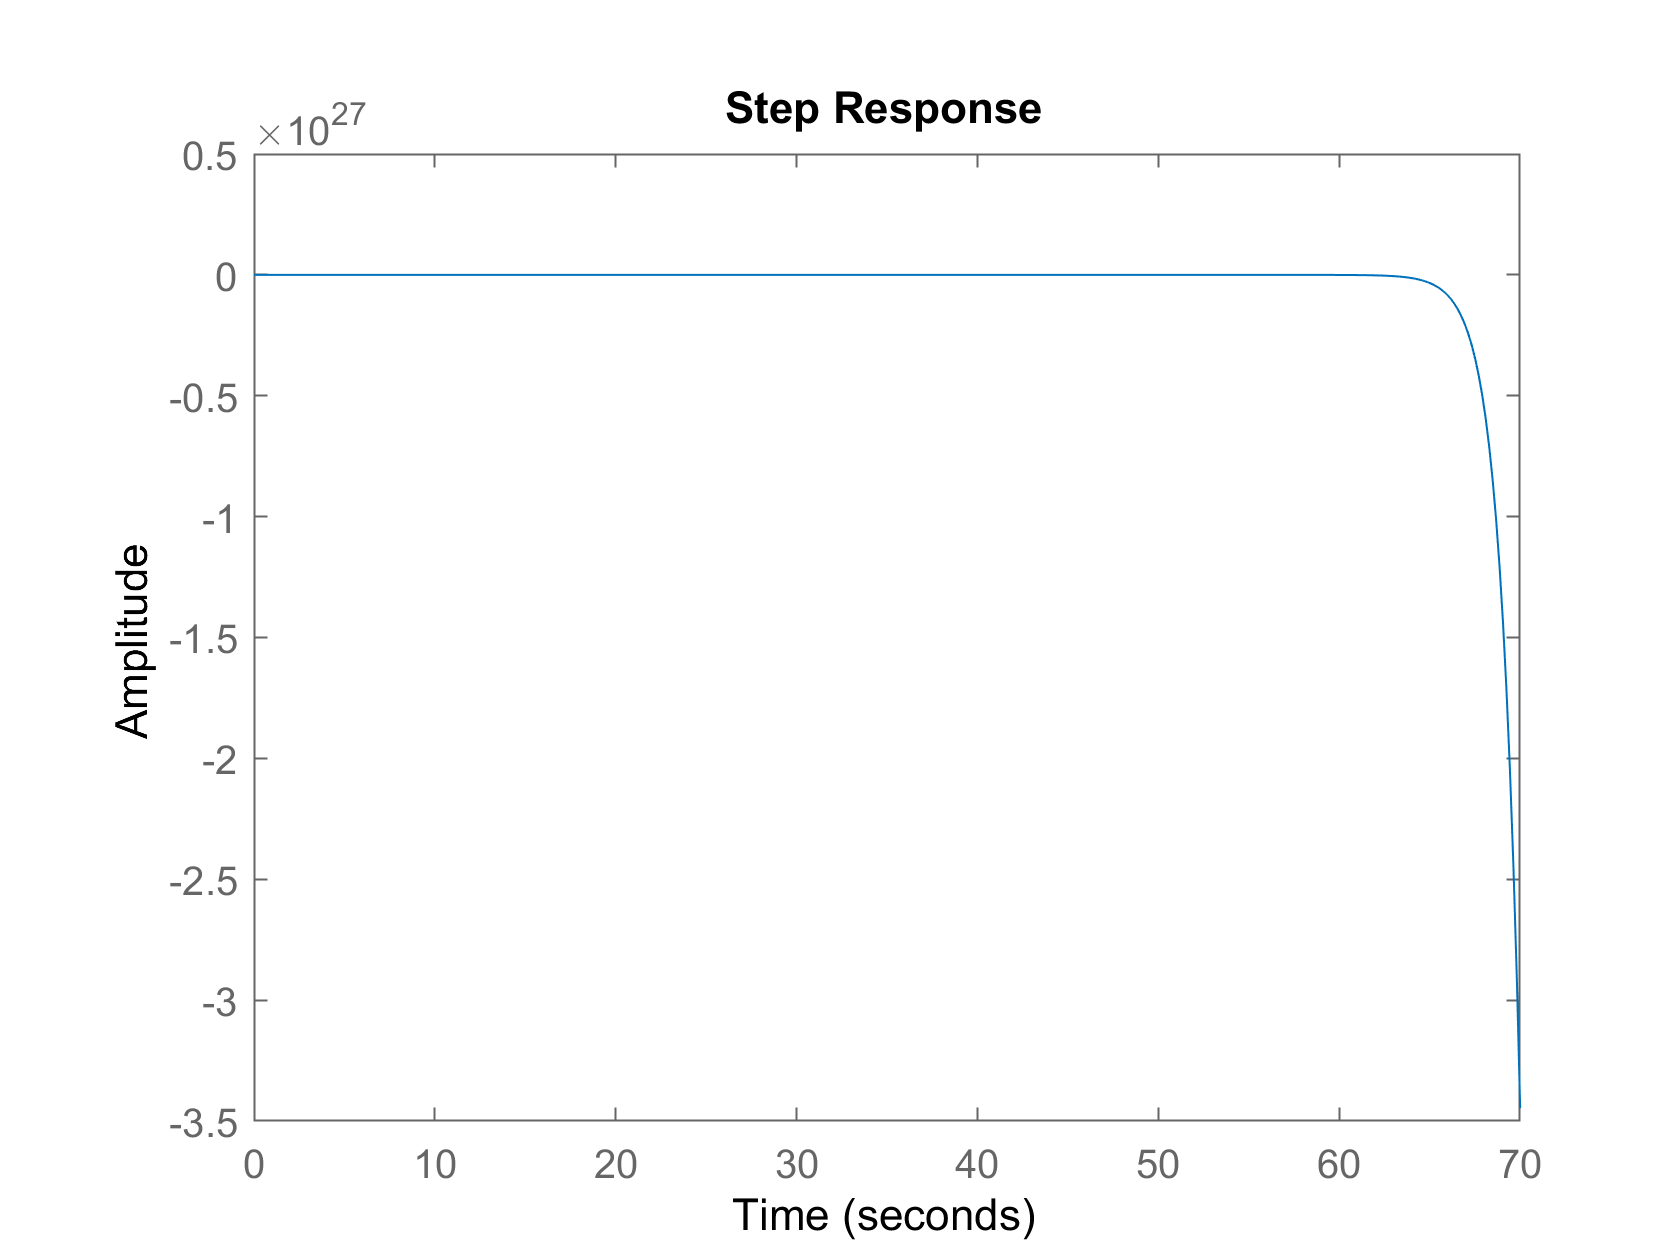

sys_cld = ss(A_d-B_d*K_d, B_d, C_d, D);
step(sys_cld);

eig(A_d-B_d*K_d)

ans =   -0.8458 + 0.0000i
  -0.0009 + 0.0000i
   0.9629 + 0.0355i
   0.9629 - 0.0355i



disp("Continuous LQR step")

Continuous LQR step


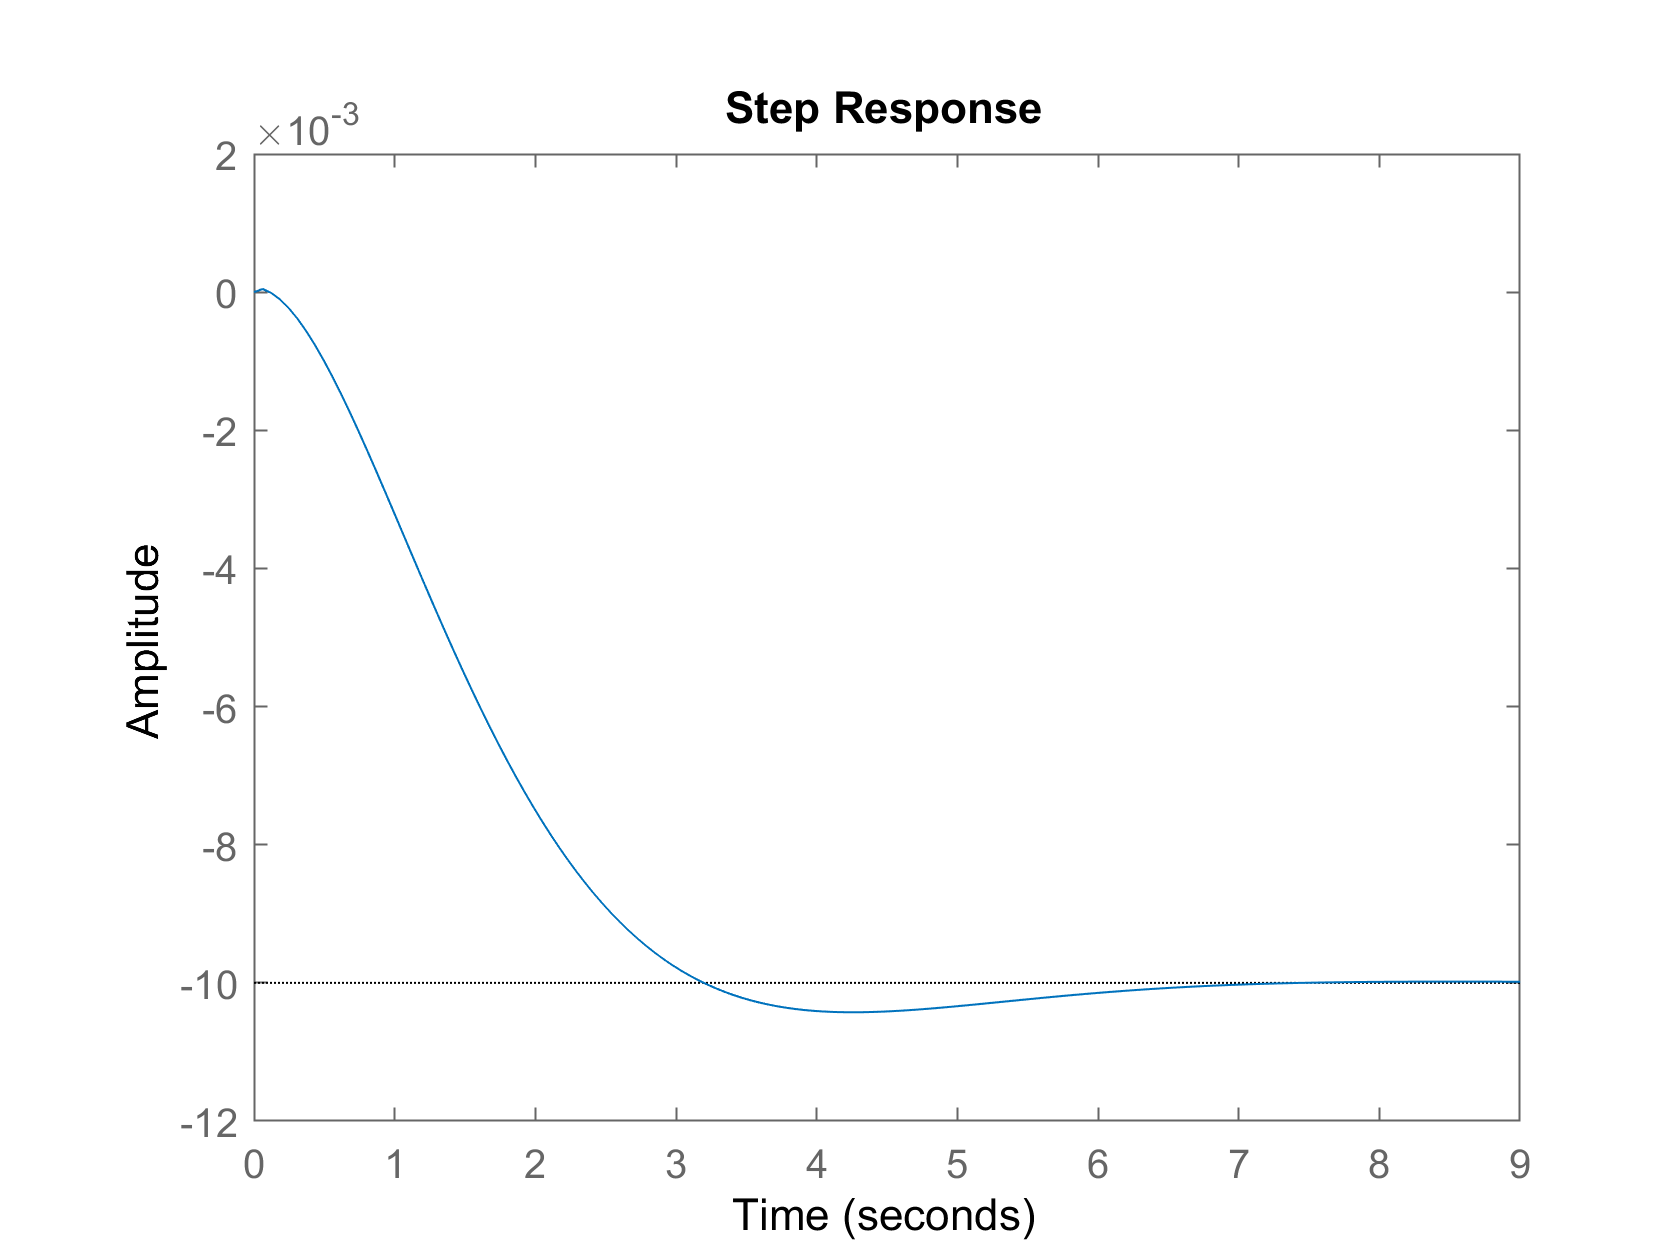

sys_cl = ss(A-B*K, B, C, D);
step(sys_cl);

sys_cl = c2d(sys_cl, 0.05, 'zoh');

A=sys_cl.A;
B=sys_cl.B;
C=sys_cl.C;

## Augmented State Space 

state_n = size(A, 1);
A_new = [A zeros(state_n,1); C 1];
B_new = [B; 0];
C_new = [C 0; zeros(1,state_n) 1];
W_new = [B*K;-1 0 0 0];

input_n = size(B_new, 2);

## MPC Formulation

N = 2;
R = 0.1; % Control penalty
Q = diag([50; 5]);  % output = [position; integral of error]
Qbar = blkdiag(Q,Q);
Rbar = blkdiag(R,R);

Tbar = [C_new*A_new;C_new*A_new^2];
Sbar = [C_new*B_new zeros(2,1);C_new*A_new*B_new C_new*B_new];
Wbar = [C_new*W_new;C_new*W_new + C_new*A_new*W_new];
H = (Rbar+Sbar'*Qbar*Sbar);
H = (H+H')/2;

G = [tril(eye(N*input_n));-tril(eye(N*input_n))];
S = zeros(2*N*input_n,5);
W = 12*ones(2*N,1);

iter = 1000;
r = 0.25*ones(iter,1);
%r = 2*square([1:iter+N+1]/200);

Xact = [];
Uopt = [];
Usys = [];
X = [0;0;0;0;0];
U = 0;

v_prev = 0;
v = 0;

U_disturb = 0;
warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';

ii=1;
tic
while (ii<iter)
    flushinput(bt); 
    fscanf(bt); 
    rawdata = fscanf(bt);
    
    X = parsedata(rawdata); 
    Usys=[Usys X(5)];
    v = v_prev + X(1) - r(ii);
    X=[X(1:4,1); v];
    
    Xact(:,ii) = X;
    Rbarref = [r(ii);0;r(ii);0];
    RR = [r(ii) 0 0 0];
    f = 2*(X'*Tbar'*Qbar*Sbar - Rbarref'*Qbar*Sbar - RR*Wbar'*Qbar*Sbar); 
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    
    Uopt(ii) = Z(1) - U_disturb;
    U = Uopt(ii);

    flushoutput(bt); 
    fprintf(bt,num2str(U)) 
    ii=ii+1;
    
    v_prev = v;
end

Index exceeds the number of array elements (1).

toc

## Plotting

Xact(:,ii+1) = X;
flushoutput(bt);
fprintf(bt,num2str(0));

%% Plotting
y=C_new*Xact;

plot([1:iter],y(1,1:iter),[1:iter],r(1:iter))
legend('y','r')
plot([1:iter],y(2,1:iter))
legend('Integral of error')
plot([1:iter-1], Uopt(1, 1:iter-1))
% hold on
% % Usys = Usys(Usys<255 & Usys>-255);
% plot(Usys*12/255)
% hold off
legend('MPC Control')